syms x

f = @(x) 8*exp(1-x) + 7*log(x)

f = function_handle with value:
    @(x)8*exp(1-x)+7*log(x)


h2 = figure(1)

h2 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [467 311 560 420]
       Units: 'pixels'

  Show all properties


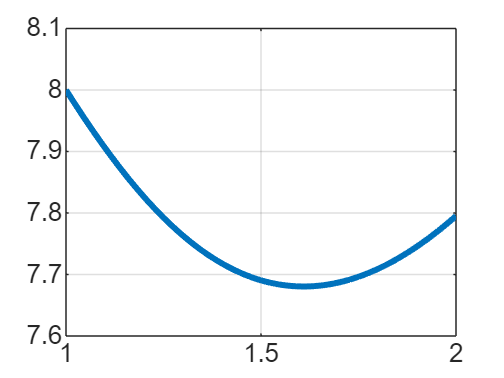

fplot(f, [1,2], linewidth =2); grid
axis([1, 2, 7.6, 8.1])


df = matlabFunction(diff(f, x));

a0 = 1; b0 = 2;
[a1, b1] = bisection_search(df, a0, b0, 5e-2)

a1 =     1.5000
    1.5000
    1.5000
    1.5625
    1.5938


b1 =     2.0000
    1.7500
    1.6250
    1.6250
    1.6250


a1(end)

ans = 1.5938

b1(end)

ans = 1.6250

%print(h2,'-depsc','E:\OneDrive\Public\workKMUTT\INC Selection Optimization\Lecture2022\figures\ic2_2025q2.eps');
%!epstopdf "E:\OneDrive\Public\workKMUTT\INC Selection Optimization\Lecture2022\figures\ic2_2025q2.eps"
